# SIMULACIÓN DEL SISTEMA

## Lazo Abierto

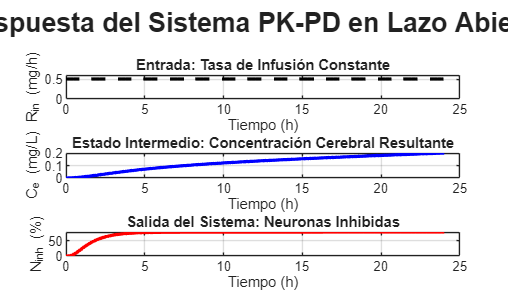


clear;
clc;
close all;

%% 1. Parámetros del Modelo Farmacocinético (PK)
% Tomados del documento del modelo PK
Vc = 15;      % L (Volumen compartimento central)
Vt = 30;      % L (Volumen compartimento periférico)
Vb = 1.5;     % L (Volumen compartimento cerebral)
Qpt = 3;      % L/h (Flujo plasma-tejido)
Qpb = 1;      % L/h (Flujo plasma-cerebro)
Cl = 1.2;     % L/h (Clearance sistémico)

% Matrices del espacio de estados para el modelo PK
A_pk = [ -(Cl+Qpt+Qpb)/Vc, Qpt/Vc, Qpb/Vc;
         Qpt/Vt, -Qpt/Vt, 0;
         Qpb/Vb, 0, -Qpb/Vb ];
B_pk = [ 1/Vc; 0; 0 ];
C_pk = [ 0, 0, 1 ]; % La salida es Cb (concentración en cerebro)

%% 2. Parámetros del Modelo Farmacodinámico (PD)
% Ajustados científicamente en el paso anterior
N_tot = 100;     % % de la población neuronal total
Kd    = 0.00303; % mg/L (Sensibilidad, análogo a EC50)
beta  = 0.8;     % 1/h  (Tasa máxima de inhibición)
alpha = 0.2;     % 1/h  (Tasa de recuperación natural)

%% 3. Simulación en Lazo Abierto
% Definición del tiempo y la entrada
t_final = 24; % horas
dt = 0.05;   % horas
t = 0:dt:t_final;

% Entrada: Tasa de infusión constante (Escalón)
R_in = 0.5; % mg/h (Puedes experimentar con este valor)
u_pk = R_in * ones(size(t)); % Vector de entrada constante

% Inicialización de los vectores de estado
x_pk = zeros(3, length(t));   % Estados PK: [Cp; Ct; Cb]
N_inh = zeros(size(t));       % Estado PD: [N_inh]

% Bucle de simulación combinado
for i = 1:length(t)-1
    % --- Etapa PK ---
    % Calcular la derivada de los estados PK
    x_pk_dot = A_pk * x_pk(:,i) + B_pk * u_pk(i);
    % Actualizar los estados PK para el siguiente paso
    x_pk(:,i+1) = x_pk(:,i) + x_pk_dot * dt;
    
    % Obtener la concentración en cerebro (salida del bloque PK)
    Ce_i = C_pk * x_pk(:,i);
    
    % --- Etapa PD ---
    % Calcular la derivada del estado PD
    dN_inh_dt = beta * (Ce_i / (Kd + Ce_i)) * (N_tot - N_inh(i)) - alpha * N_inh(i);
    % Actualizar el estado PD para el siguiente paso
    N_inh(i+1) = N_inh(i) + dN_inh_dt * dt;
end

% La concentración cerebral es el tercer estado del modelo PK
Ce_t = x_pk(3, :);

%% 4. Visualización de Resultados
figure;
sgtitle('Respuesta del Sistema PK-PD en Lazo Abierto', 'FontSize', 16, 'FontWeight', 'bold');

% Gráfica 1: Entrada (Tasa de Infusión)
subplot(3,1,1);
plot(t, u_pk, 'k--', 'LineWidth', 2);
title('Entrada: Tasa de Infusión Constante');
xlabel('Tiempo (h)');
ylabel('R_{in} (mg/h)');
ylim([0 R_in*1.2]);
grid on;

% Gráfica 2: Estado Intermedio (Concentración en Cerebro)
subplot(3,1,2);
plot(t, Ce_t, 'b-', 'LineWidth', 2);
title('Estado Intermedio: Concentración Cerebral Resultante');
xlabel('Tiempo (h)');
ylabel('C_e (mg/L)');
grid on;

% Gráfica 3: Salida (Neuronas Inhibidas)
subplot(3,1,3);
plot(t, N_inh, 'r-', 'LineWidth', 2);
title('Salida del Sistema: Neuronas Inhibidas');
xlabel('Tiempo (h)');
ylabel('N_{inh} (%)');
grid on;

## Controlador PID lazo cerrado

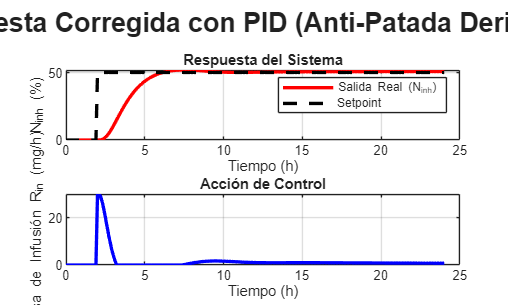

%% SIMULACIÓN EN LAZO CERRADO CON CONTROLADOR PID MEJORADO
%--------------------------------------------------------------------------
% Se implementa una estructura de PID que evita la "patada derivativa"
% al calcular la acción derivativa sobre la medida en lugar del error.
%--------------------------------------------------------------------------

clear;
clc;
close all;

%% 1. Parámetros de la Planta (PK y PD) - Sin cambios
Vc = 15; V_t = 30; Vb = 1.5; Qpt = 3; Qpb = 1; Cl = 1.2;
A_pk = [ -(Cl+Qpt+Qpb)/Vc, Qpt/Vc, Qpb/Vc; Qpt/V_t, -Qpt/V_t, 0; Qpb/Vb, 0, -Qpb/Vb ];
B_pk = [ 1/Vc; 0; 0 ];
C_pk = [ 0, 0, 1 ];
N_tot = 100; Kd = 0.00303; beta = 0.9; alpha = 0.3;

%% 2. Parámetros del Controlador PID (Valores Sintonizados)
% Usamos los valores que te sugerí para la sintonización
Kp =  0.6;  % Ganancia Proporcional Reducida
Ki =0.015;  % Ganancia Integral
Kd = 1;   % Ganancia Derivativa Aumentada

%% 3. Definición del Setpoint y Simulación
t_final = 24; dt = 0.1; t = 0:dt:t_final;
Setpoint = 50 * (t >= 2);

% Inicialización de variables
x_pk = zeros(3, length(t));
N_inh = zeros(size(t));
R_in = zeros(size(t));
error_integral = 0;
N_inh_previo = 0; % <-- Variable nueva para el cálculo derivativo

%% 4. Bucle de Simulación en Lazo Cerrado (CON LA CORRECCIÓN)
for i = 1:length(t)-1
    % --- Controlador ---
    % 1. Calcular el error (para los términos P e I)
    error = Setpoint(i) - N_inh(i);
    
    % 2. Calcular el término integral
    error_integral = error_integral + error * dt;
    
    % --- TÉRMINO DERIVATIVO (SOBRE LA MEDIDA, NO EL ERROR) ---
    % 3. Calcular la derivada de la salida del sistema
    derivada_salida = (N_inh(i) - N_inh_previo) / dt;
    % Guardar el valor actual para la siguiente iteración
    N_inh_previo = N_inh(i);
    % -------------------------------------------------------------
    
    % 4. Calcular la acción de control total
    % ¡Observa el signo MENOS en el término derivativo!
    accion_control = Kp * error + Ki * error_integral - Kd * derivada_salida;
    
    % Aplicar restricciones
    if accion_control < 0
        accion_control = 0;
    end
    R_in(i) = accion_control;
    
    % --- Planta (PK-PD) ---
    % El resto de la simulación de la planta es igual
    x_pk_dot = A_pk * x_pk(:,i) + B_pk * R_in(i);
    x_pk(:,i+1) = x_pk(:,i) + x_pk_dot * dt;
    Ce_i = C_pk * x_pk(:,i+1);
    
    termino_inhibicion = beta * (Ce_i / (Kd + Ce_i)) * (N_tot - N_inh(i));
    termino_recuperacion = alpha * N_inh(i);
    dN_inh_dt = termino_inhibicion - termino_recuperacion;
    N_inh(i+1) = N_inh(i) + dN_inh_dt * dt;
end
R_in(end) = R_in(end-1);

%% 5. Visualización de Resultados
figure;
sgtitle('Respuesta Corregida con PID (Anti-Patada Derivativa)', 'FontSize', 16, 'FontWeight', 'bold');
subplot(2,1,1);
plot(t, N_inh, 'r-', 'LineWidth', 2); hold on;
plot(t, Setpoint, 'k--', 'LineWidth', 2);
title('Respuesta del Sistema'); xlabel('Tiempo (h)'); ylabel('N_{inh} (%)');
legend('Salida Real (N_{inh})', 'Setpoint'); grid on;

subplot(2,1,2);
plot(t, R_in, 'b-', 'LineWidth', 2);
title('Acción de Control'); xlabel('Tiempo (h)'); ylabel('Tasa de Infusión R_{in} (mg/h)');
grid on;

## Segundo Control

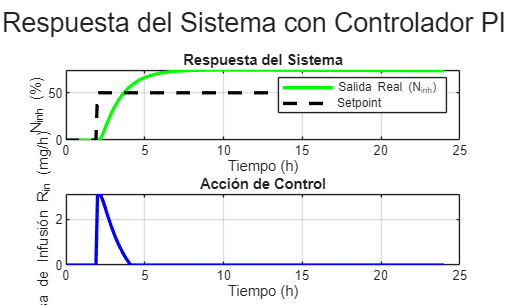

%% SIMULACIÓN EN LAZO CERRADO CON CONTROLADOR PI
clear; clc; close all;

%% 1. Parámetros de la Planta (PK y PD)
Vc = 15; V_t = 30; Vb = 1.5; Qpt = 3; Qpb = 1; Cl = 1.2;
A_pk = [ -(Cl+Qpt+Qpb)/Vc, Qpt/Vc, Qpb/Vc; Qpt/V_t, -Qpt/V_t, 0; Qpb/Vb, 0, -Qpb/Vb ];
B_pk = [ 1/Vc; 0; 0 ];
C_pk = [ 0, 0, 1 ];
N_tot = 100; Kd = 0.00303; beta = 0.6; alpha = 0.2;

%% 2. Parámetros del Controlador PI
Kp = 0.06;
Ki = 0.01;

%% 3. Simulación
t_final = 24; dt = 0.1; t = 0:dt:t_final;
Setpoint = 50 * (t >= 2);

x_pk = zeros(3, length(t));
N_inh = zeros(size(t));
R_in = zeros(size(t));
error_integral = 0;

for i = 1:length(t)-1
    error = Setpoint(i) - N_inh(i);
    error_integral = error_integral + error * dt;
    
    accion_control = Kp * error + Ki * error_integral;
    
    if accion_control < 0, accion_control = 0; end
    R_in(i) = accion_control;
    
    x_pk_dot = A_pk * x_pk(:,i) + B_pk * R_in(i);
    x_pk(:,i+1) = x_pk(:,i) + x_pk_dot * dt;
    Ce_i = C_pk * x_pk(:,i+1);
    
    dN_inh_dt = beta*(Ce_i/(Kd+Ce_i))*(N_tot-N_inh(i)) - alpha*N_inh(i);
    N_inh(i+1) = N_inh(i) + dN_inh_dt * dt;
end
R_in(end) = R_in(end-1);

%% 5. Visualización
figure;
sgtitle('Respuesta del Sistema con Controlador PI', 'FontSize', 16);
subplot(2,1,1);
plot(t, N_inh, 'g-', 'LineWidth', 2); hold on;
plot(t, Setpoint, 'k--', 'LineWidth', 2);
title('Respuesta del Sistema'); xlabel('Tiempo (h)'); ylabel('N_{inh} (%)');
legend('Salida Real (N_{inh})', 'Setpoint'); grid on;
subplot(2,1,2);
plot(t, R_in, 'b-', 'LineWidth', 2);
title('Acción de Control'); xlabel('Tiempo (h)'); ylabel('Tasa de Infusión R_{in} (mg/h)');
grid on;